# 로봇 비전 HW1

due date : 10월 13일 23:59

코드 작성한 후 본인의 Github에 업로드하고 Repository URL을 적으세요. 

GitHub URL : 

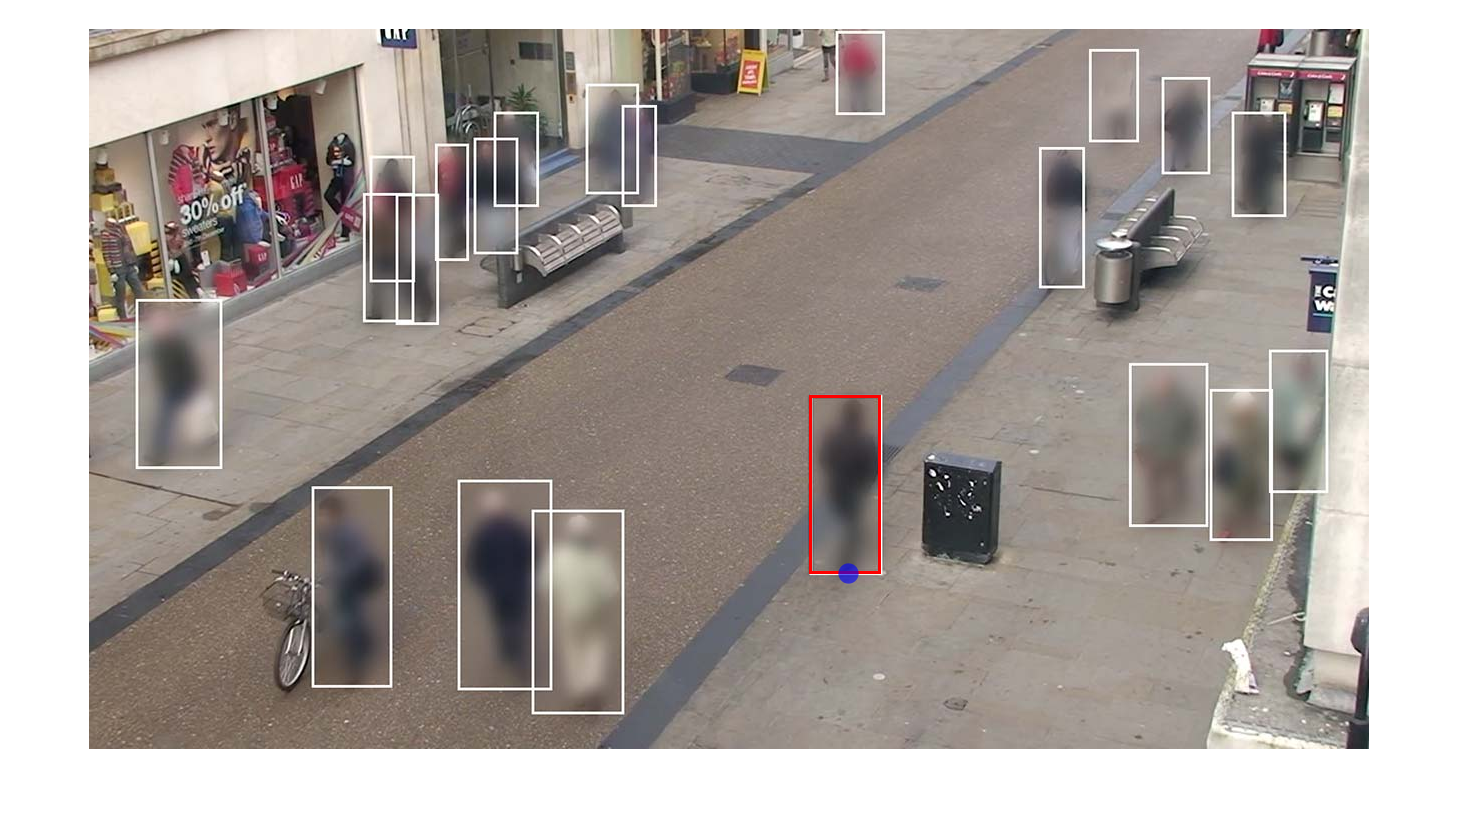

% image 정보 불러오기
img = imread("C:\Users\hyeon\Desktop\로봇비전\HW1\background.jpg");
img_rec = insertShape(img, 'Rectangle', [722 368 70 177], 'Color', "red", 'LineWidth', 3);      % 사각형 그리기
img_rec = insertShape(img_rec, 'FilledCircle', [760 545 10], 'Color', "blue", 'LineWidth', 10); 
figure(2);
imshow(img_rec);

- 임의의 카메라의 설치 위치와 각도에 따라 사람의 발(파란 점)의 3차원 좌표를 구하는 Matlab 코드를 작성하세요. 

- World Coordinate 원점에 대한 카메라의 위치는 다음과 같다.

- 카메라의 위치는 R과 t로 주어진다. 

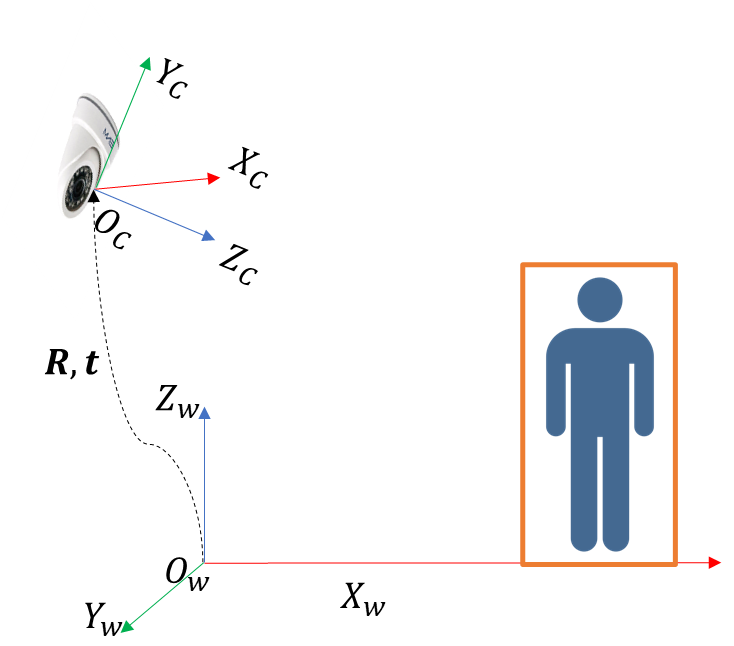

- f_x = 1000 pixel, f_y = 1000 pixel

- c_x = 640 pixel, c_y = 480 pixel

- 이미지 size : 1280*720

- 이미지 상 파란 점의 위치 : (760, 545)

% Intrinsic Parameters
fx = 1000;
fy = 1000;
cx = 640;
cy = 480;

% 파란점의 픽셀 위치
u = 760;
v = 545;

% 임의의 카메라 설치 위치
theta_x = (pi/2) - (pi/6);  % x축 각도
theta_y = -pi/2;        % y축 각도
theta_z = pi/2;         % z축 각도

% 위치
tx = 0;
ty = -5;
tz = 0.2;


% Camera Matrix?
K = [
    fx  0  cx;
    0  fx  cy;
    0   0  1]

K =         1000           0         640
           0        1000         480
           0           0           1



% Rotation Matrix?
Rz = [
    cos(theta_z) -sin(theta_z) 0;
    sin(theta_z) cos(theta_z) 0;
    0 0 1];
Ry = [
    cos(theta_y) 0 sin(theta_y);
    0 1 0;
    -sin(theta_y) 0 cos(theta_y)];

Rx = [
    1 0 0;
    0 cos(theta_x) -sin(theta_x);
    0 sin(theta_x) cos(theta_x)];

R = Rz*Ry*Rx

R =     0.0000   -0.5000    0.8660
    0.0000   -0.8660   -0.5000
    1.0000    0.0000    0.0000


r1 = R(:, 1)

r1 =     0.0000
    0.0000
    1.0000


r2 = R(:, 2)

r2 =    -0.5000
   -0.8660
    0.0000


r3 = R(:, 3)

r3 =     0.8660
   -0.5000
    0.0000


% Translation Matrix?
t = [tx; ty; tz]

t =          0
   -5.0000
    0.2000




% World Coordinate 좌표 값?

p_img = [u; v; 1];

% s * p_img = K * [R|t] * [Xw; Yw; Zw; 1]  // s = scale factor

% inv(K)*(s * p_img) = r1*Xw + r2*Yw + t  >>> Zw = 0

% [inv(K)*p_img, -r1, -r2] * [s; Xw; Yw] = t

% [s; Xw; Yw] = inv([inv(K)*p_img, -r1, -r2]) * t

inv([inv(K)*p_img, -r1, -r2]) * t

ans =    35.0027
   34.8027
   -8.4006


World = [34.8042; -8.4010; 0]

World =    34.8042
   -8.4010
         0



inv([inv(K)*p_img, -r1, -r2]) * t

ans =    35.0027
   34.8027
   -8.4006
